[Defining An Ultrasound Transducer](https://www.k-wave.org/documentation/example_us_defining_transducer.php)

En principio, la mayoria de simulaciones usando transductores con ultrasonido pueden ser eealizados siguiendo los ejemplo de  [Time Varying Source Problems](https://www.k-wave.org/documentation/k-wave_time_varying_source_problems.php). Sin embargo, asignar los puntos que corresponden al elemento de transductor y lo que conlleva es muy tardado.

Por esta razon, existe **kWaveTransducer** class que puede sustituir la fuente o el sensor o ambos. Para este ejemplo mostraremos como se realiza lo siguiente mediante un campo producido por un trasnductor de ultrasonido.

Los inputs de trasnductor solo pueden usarse en simulaciones 3D, y gastan mucha memora y cpu. Para reducir el gasto computacional, los calculos usan double (8 bytes), sin embargo mejor usaremos single (4 bytes), para ello hacemos: (`'DataCast','single').`

if you have access to a recent model GPU and the MATLAB Parallel Computing Toolbox R2012a or later, the simulation times can be significantly reduced by setting `'DataCast'` to `'gpuArray-single'`

#### **Definimos la senal de entrada**

Primero definimos la senal que sera usada y luego el transductor en ese orden.

Dependiendo del angulo y distancia de enfoque del transductor los **retardos de beamforming **se calculan automaticamente en k-wave.


%sin steering:
%E1  E2  E3  E4  E5
% \   \  |  /   /
%      foco

%con steering:
%E1  E2  E3  E4  E5
%      \   \   \   \
%            ↘ haz

Note, the properties of the input signal are dependent on the time step used in the simulation, so `kgrid.t_array` must be defined before creating the input signal.

Para crear la senal usamos **toneBurst**: This creates a single frequency sinusoid with a given number of cycles windowed by a Gaussian. 

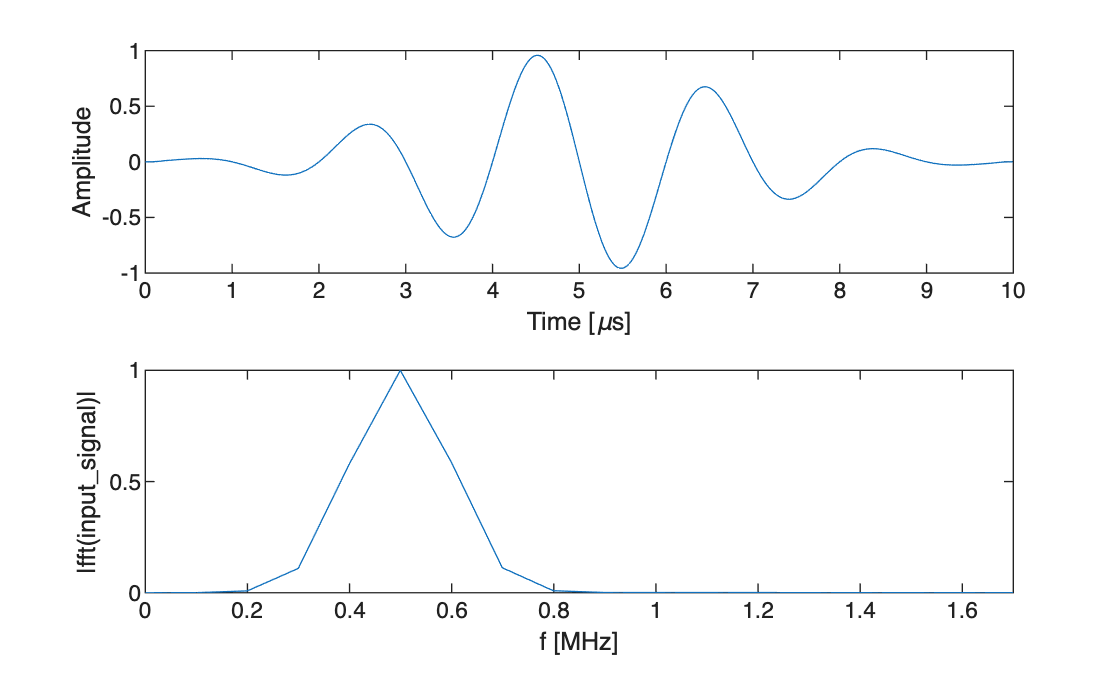

%Defino espacio y tiempo de simulacion
% crear grid 3D (porque el transductor es tridimensional)
Nx = 128;
Ny = 128;
Nz = 64;

dx = 0.1e-3;
dy = 0.1e-3;
dz = 0.1e-3;

kgrid = kWaveGrid(Nx,dx,Ny,dy,Nz,dz);

% definir medio
medium.sound_speed = 1540;   % [m/s]
medium.density = 1000;       % [kg/m^3]

% definir el tiempo de simulacion
kgrid.t_array = makeTime(kgrid,medium.sound_speed);


%---------- Nuevo--------------
% define properties of the input signal
source_strength = 1e6;          % [MPa]
tone_burst_freq = 0.5e6;        % [Hz]
tone_burst_cycles = 5; 

%T= 10 us=1e-5 s 
% Necesito kgrid.dt antes para construir el input signal, entonces
% por eso debo definir el timepo de simulacion antes.
input_signal = toneBurst(1/kgrid.dt, tone_burst_freq, tone_burst_cycles);
t = (0:length(input_signal)-1)*kgrid.dt;

%Ploto el pulso que estoy mandando de 5 ciclos 
% señal temporal
t = (0:length(input_signal)-1)*kgrid.dt;

figure;

subplot(2,1,1);
plot(t*1e6,input_signal);
xlabel('Time [\mus]');
ylabel('Amplitude');

Y = fft(input_signal);
Y_abs = Y/max(Y);

L = length(input_signal);
Fs = 1/kgrid.dt;

subplot(2,1,2);
plot(Fs/L*(0:L-1)*1e-6,abs(Y_abs));
xlabel('f [MHz]');
ylabel('|fft(input\_signal)|');
xlim([0 1.7]);

#### **Definimos el transductor**

This is accomplished by creating an object of the [`kWaveTransducer`](https://www.k-wave.org/documentation/kWaveTransducer.php) class.

First, the physical properties of the transducer are defined, including the number of elements and their size. The sizes are all given in units of grid points which means the physical size is also dependent on the values of `kgrid.dx`, `kgrid.dy`, and `kgrid.dz`.

The `radius` input will be used in future versions of k-Wave to create curved transducers. Solo esta el transductor lineal soportado por el momento.

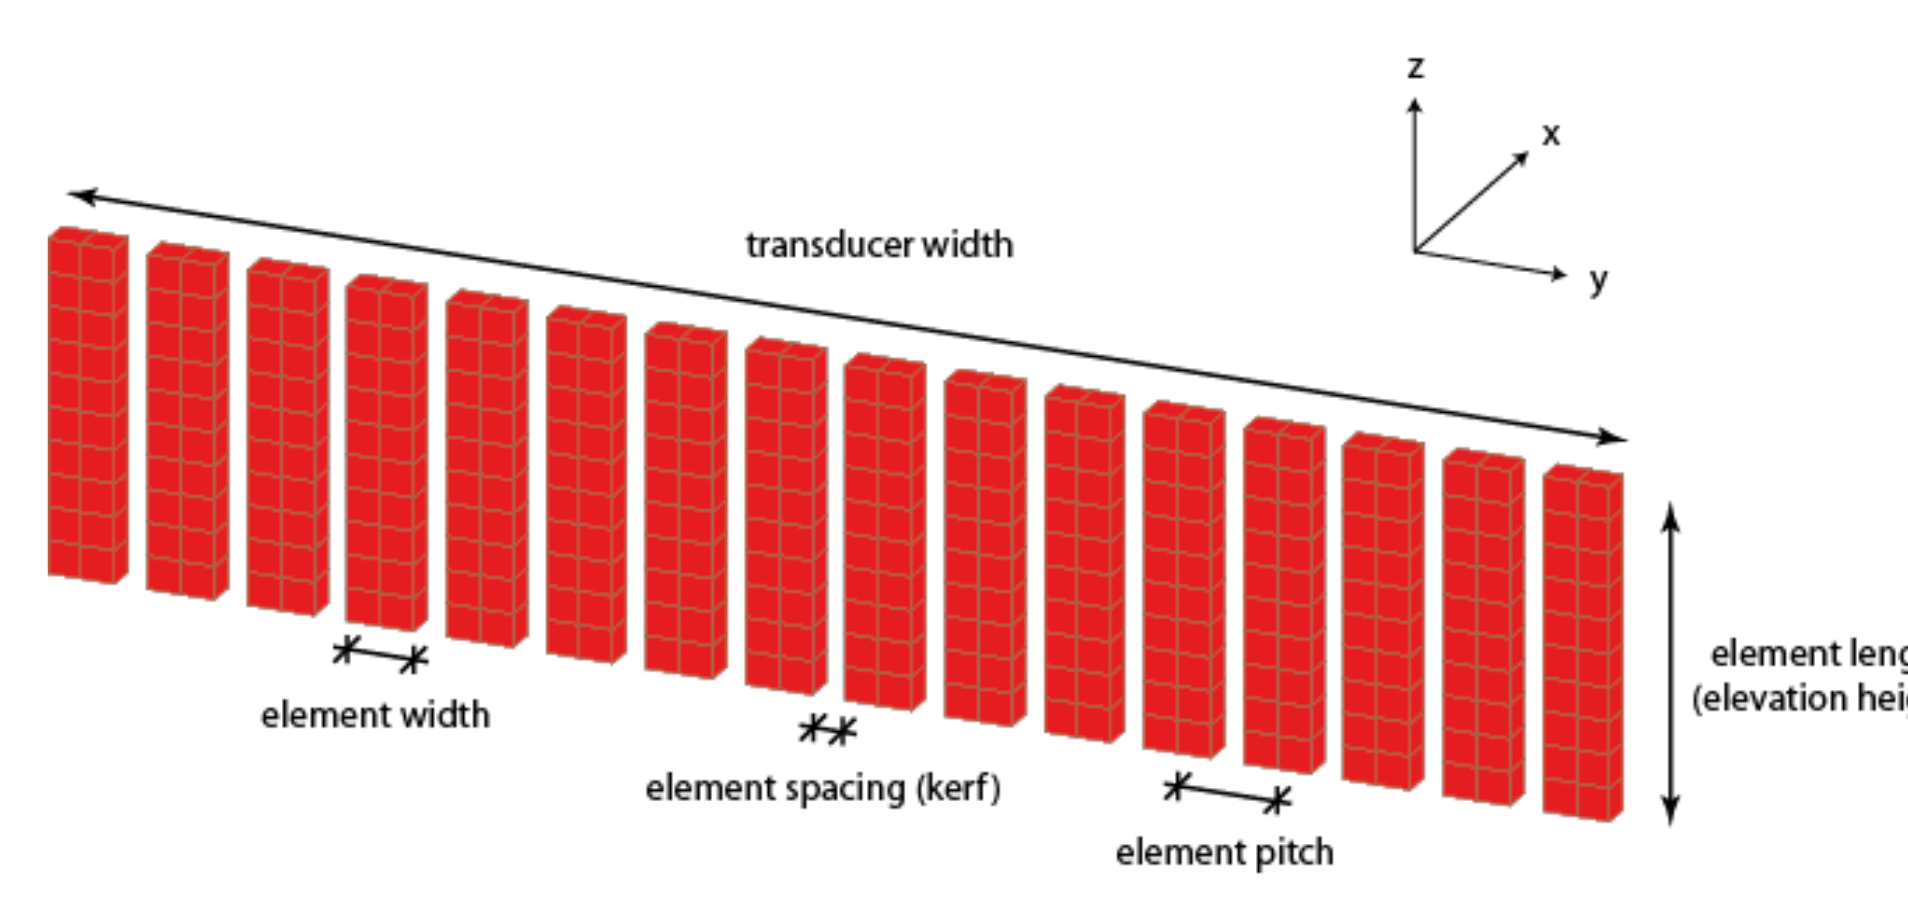

% physical properties of the transducer
transducer.number_elements = 72;    % total number of transducer elements
transducer.element_width = 1;       % width of each element [grid points]
transducer.element_length = 12;     % length of each element [grid points]
transducer.element_spacing = 0;     % spacing (kerf width) between the elements [grid points]
transducer.radius = inf;            % radius of curvature of the transducer [m]

% calculate the width of the transducer in grid points
transducer_width = transducer.number_elements * transducer.element_width ...
    + (transducer.number_elements - 1) * transducer.element_spacing;

% use this to position the transducer in the middle of the computational grid
transducer.position = round([1, Ny/2 - transducer_width/2, Nz/2 - transducer.element_length/2]);


Next, the dynamic properties of the transducer are defined. k-Wave calcula **dos tipos de retardos de beamforming, **sound speed + focus distance + steering angle, 

% properties used to derive the beamforming delays
transducer.sound_speed = 1540;                  % sound speed [m/s]
transducer.focus_distance = 20e-3;              % focus distance [m]
transducer.elevation_focus_distance = 19e-3;    % focus distance in the elevation plane [m]
transducer.steering_angle = 0;                  % steering angle [degrees]

**Apodization:** controla el **peso/amplitud relativa** aplicada a cada elemento activo del transductor.

- con una ventana de `getWin` (por ejemplo `'Hanning'`, `'Hamming'`, etc.),

- con un vector manual de pesos, 

- o dejarse sin definir, en cuyo caso usa `'Rectangular'` por defecto.

% apodization
transducer.transmit_apodization = 'Rectangular';    
transducer.receive_apodization = 'Rectangular';

%Un transductor puede tener muchos elementos físicos, 
% pero no necesariamente todos se usan al mismo tiempo

% define the transducer elements that are currently active
transducer.active_elements = zeros(transducer.number_elements, 1);
transducer.active_elements(21:52) = 1;

% La señal que genere con toneBurst se asigna al transductor:
transducer.input_signal = input_signal;

Antes de esta línea, `transducer` es solo una estructura con parámetros. Después pasa a ser un objeto `kWaveTransducer`, con propiedades y métodos adicionales.

% create the transducer using the defined settings
transducer = kWaveTransducer(kgrid, transducer);


 
k-Wave Transducer Properties
  transducer position:       [1  28  26]
  transducer width:          7.2mm (72 grid points)
  number of elements:        72
  number of active elements: 32 (elements 21 to 52)
  element width:             100um (1 grid points)
  element spacing (kerf):    0m (0 grid points)
  element pitch:             100um (1 grid points)
  element length:            1.2mm (12 grid points)
  sound speed:               1540m/s
  focus distance:            20mm
  elevation focus distance:  19mm
  steering angle:            0 degrees
  steering angle max:        auto degrees


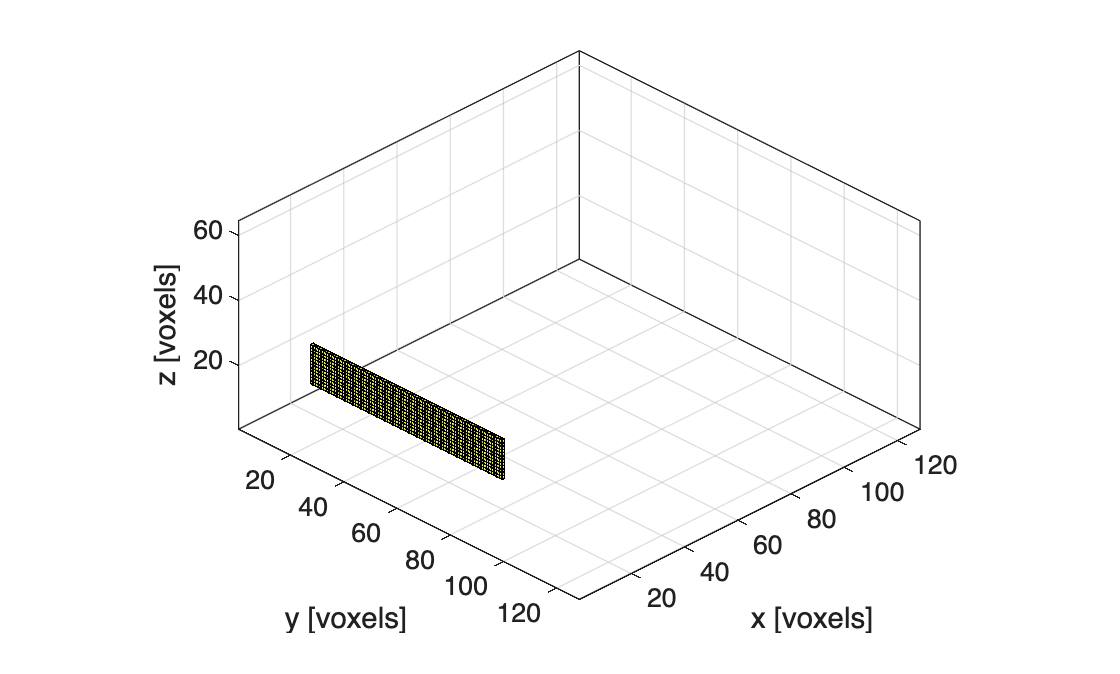

%Para revisar las propieades del transductor
transducer.properties

%Para plotear el transductor en el espacio tridimensional
transducer.plot

Ahora para correr la simulacion usaremos kspaceFirstOrder3D, aqui por ejemplo el transductor reempalza source input, pero aun no sensor (aplicaremos una binary mask para eso)

%Para medir en puntos concretos y ver como llega la onda en esos
sensor.mask = zeros(Nx,Ny,Nz);

%3 sensores en puntos concretos
sensor.mask(50,64,32) = 1;
sensor.mask(70,64,32) = 1;
sensor.mask(90,64,32) = 1;

`BonA` controla la **no linealidad acústica**. Al definirlo, k-Wave ya no simula solo propagación lineal, sino que incluye la distorsión no lineal de la onda.

% run the simulation
input_args = {'DataCast','single','PMLInside',false};

Running k-Wave simulation...
  start time: 27-Aug-2026 12:17:53
  reference sound speed: 1540m/s
  prepending transducer.input_signal with 2 leading zeros
  appending transducer.input_signal with 2 trailing zeros
  dt: 19.4805ns, t_end: 12.4675us, time steps: 641
  input grid size: 128 by 128 by 64 grid points (12.8 by 12.8 by 6.4mm)
  maximum supported frequency: 7.7MHz
  expanding computational grid...
  computational grid size: 148 by 148 by 84 grid points
           Use dimension sizes with lower prime factors to improve speed
  casting variables to single type...
  precomputation completed in 0.58624s
  starting time loop...
  estimated simulation time 54.2439s...
  simulation completed in 59.4567s
  total computation time 1min 0.084628s


%smooth solo genera inconvenientes cuando se usa ene source
%[sensor_data] = kspaceFirstOrder3D(kgrid, medium, transducer, sensor, input_args{:});

**1. Dominio temporal:** `sensor_data` muestra cómo cambia la presión con el tiempo en cada sensor. Al propagarse una onda de amplitud alta por un medio no lineal, la forma del pulso puede ir deformándose.

**2. Dominio de frecuencia:** al aplicar FFT a cada señal registrada, observas qué frecuencias contiene. 

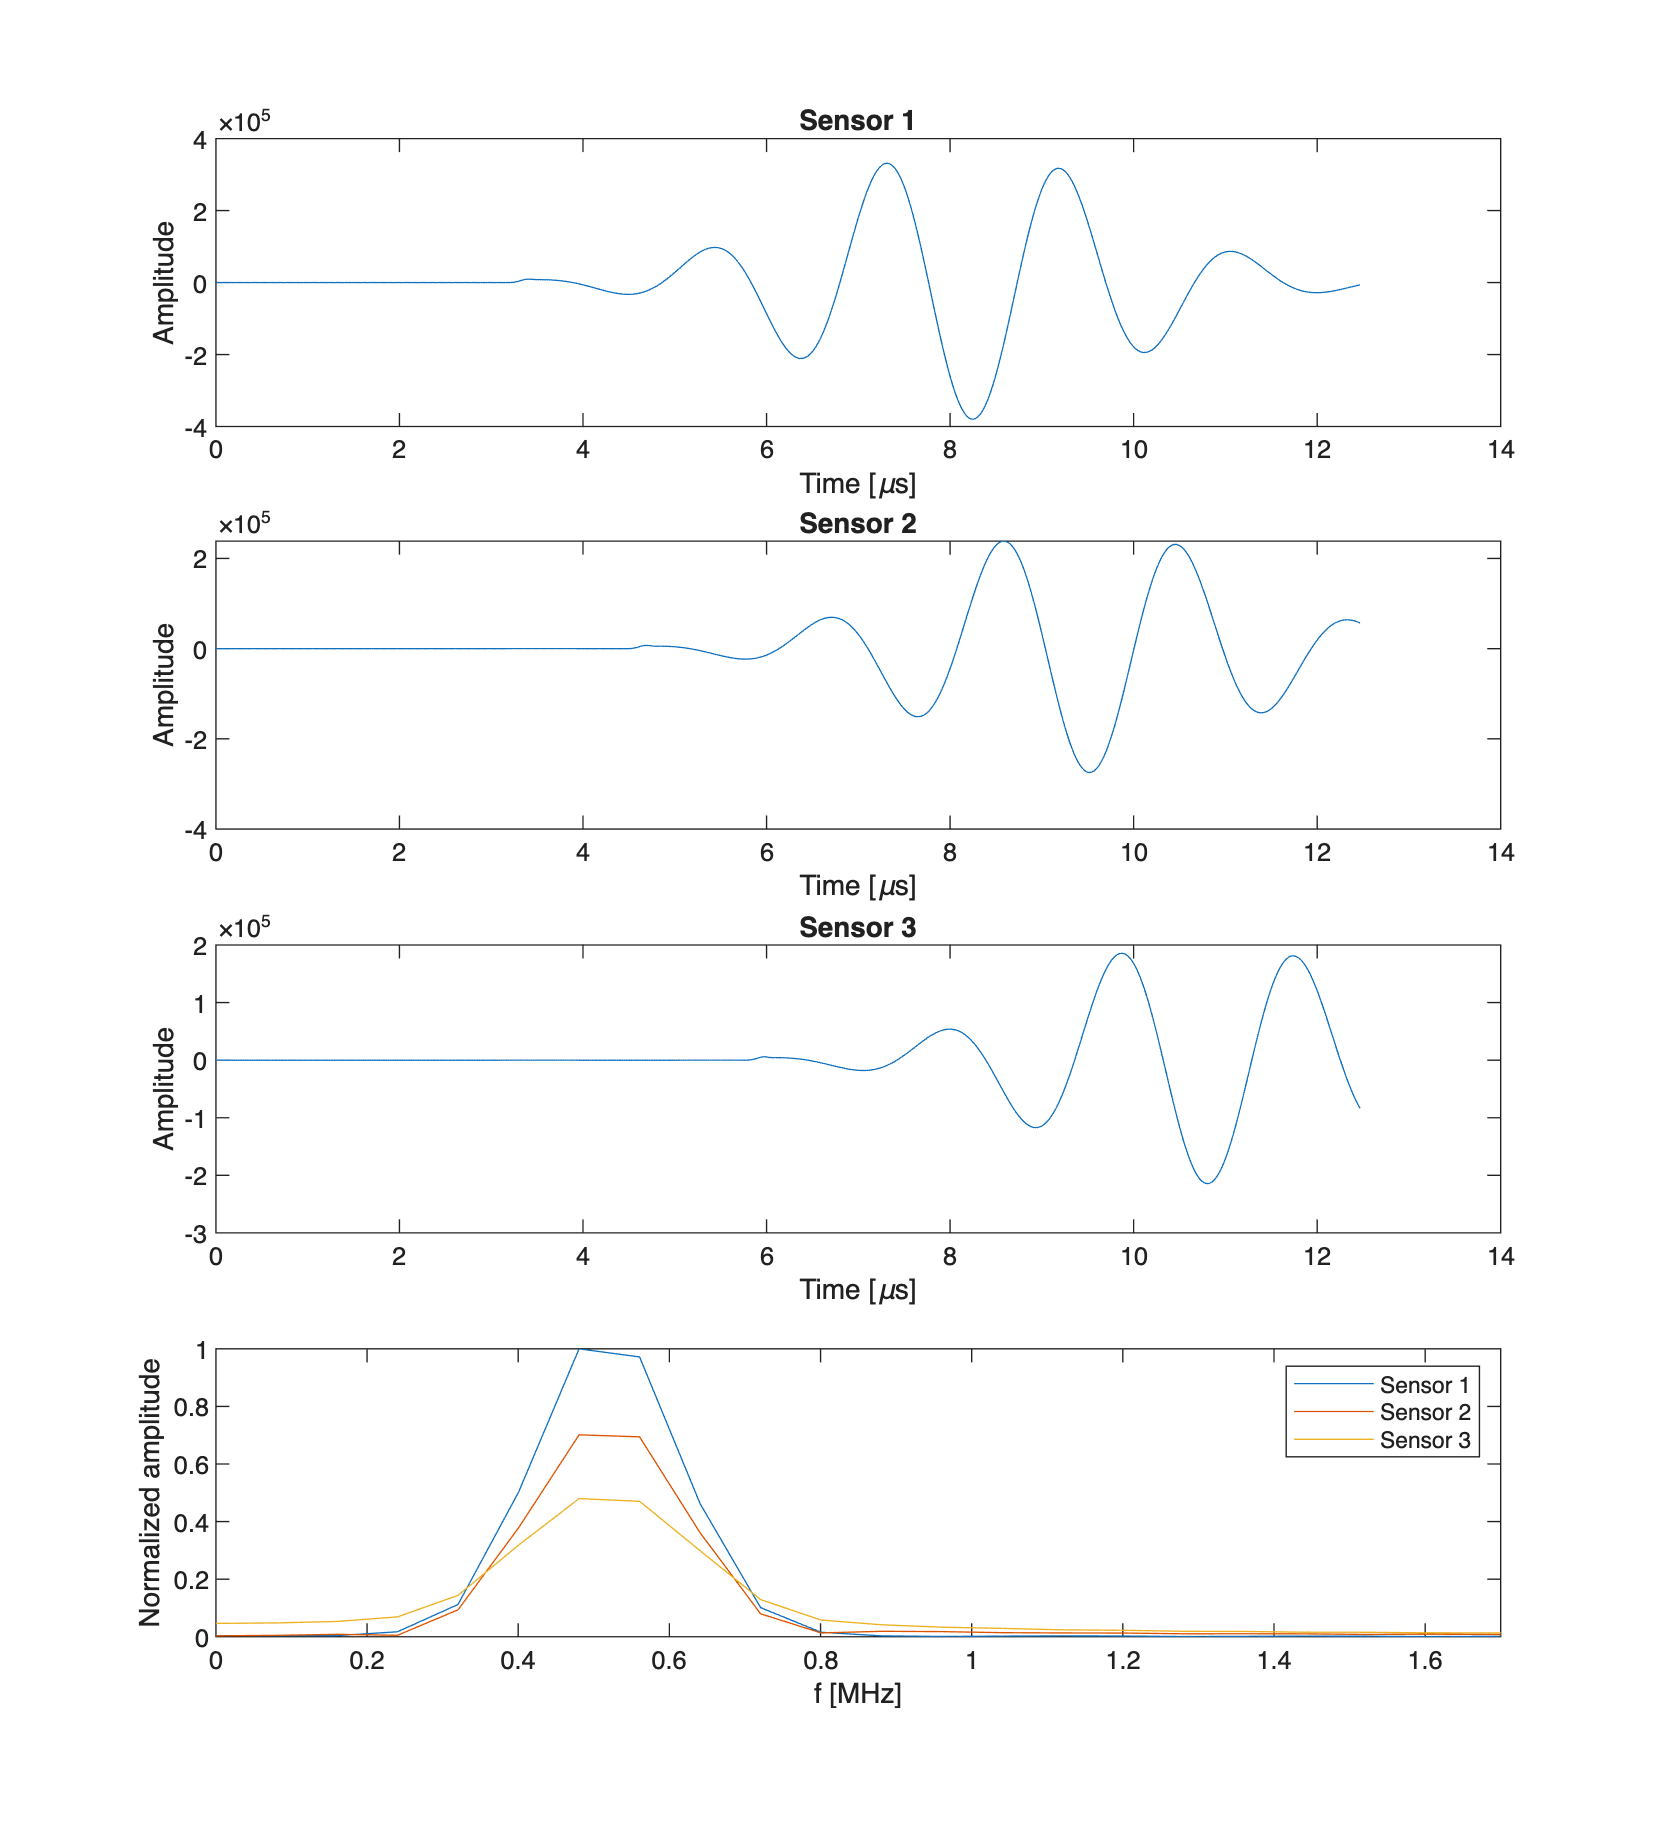


t = kgrid.t_array;

figure('Position',[100 100 900 1000]);
%temporal
subplot(4,1,1);
plot(t*1e6,sensor_data(1,:));
xlabel('Time [\mus]');
ylabel('Amplitude');
title('Sensor 1');

subplot(4,1,2);
plot(t*1e6,sensor_data(2,:));
xlabel('Time [\mus]');
ylabel('Amplitude');
title('Sensor 2');

subplot(4,1,3);
plot(t*1e6,sensor_data(3,:));
xlabel('Time [\mus]');
ylabel('Amplitude');
title('Sensor 3');

%Espectral
Y1 = fft(sensor_data(1,:));
Y2 = fft(sensor_data(2,:));
Y3 = fft(sensor_data(3,:));

L = size(sensor_data,2);
Fs = 1/kgrid.dt;

Y1_abs = abs(Y1)/max(abs(Y1));
Y2_abs = abs(Y2)/max(abs(Y1));
Y3_abs = abs(Y3)/max(abs(Y1));

subplot(4,1,4);
plot(Fs/L*(0:L-1)*1e-6,Y1_abs);
hold on;
plot(Fs/L*(0:L-1)*1e-6,Y2_abs);
plot(Fs/L*(0:L-1)*1e-6,Y3_abs);

xlabel('f [MHz]');
ylabel('Normalized amplitude');

legend('Sensor 1','Sensor 2','Sensor 3');
xlim([0 1.7]);

Al definir** 3 sensores a distintas profundidades: **cuanto mayor es la profundidad del sensor, mayor es el tiempo de llegada, por ello la onda va perdiendo amplitud conforme se propaga a mas distancia recorrida se puede observar una mayor atenuacion. Asimismo el transductor está **focalizado, **por lo que depende tambien si cada sensor está antes, cerca o después del foco. El haz se concentra hacia la región focal y luego vuelve a divergir.

[Simulating Ultrasound Beam Patterns](https://www.k-wave.org/documentation/example_us_beam_patterns.php)

[Example: Using An Ultrasound Transducer As A Sensor](https://www.k-wave.org/documentation/example_us_transducer_as_sensor.php)

[Example: Simulating B-mode Ultrasound Images](https://www.k-wave.org/documentation/example_us_bmode_linear_transducer.php)

[Example: Simulating B-mode Images Using A Phased Array](https://www.k-wave.org/documentation/example_us_bmode_phased_array.php)